% Read file
file = readtable("deepseek_vs_chatgpt.csv");

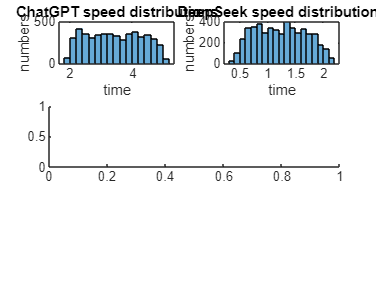

% Analyze the Speed for DeepSeek and ChatGPT

% Create speed table
gptSpeed = table2array(file(strcmp(file.AI_Platform, 'ChatGPT'), 'Response_Speed_sec'));
deepseekSpeed =table2array(file(strcmp(file.AI_Platform, 'DeepSeek'), 'Response_Speed_sec'));

% Two graph to show the distributions
% 1st graph, the distribution of Response_Speed_sec

subplot(3,2,1)
histogram(gptSpeed)
xlabel("time")
ylabel("numbers")
title("ChatGPT speed distributions")

% 2ed graph, the distribution of Response_Speed_sec
subplot(3,2,2)
histogram(deepseekSpeed)
xlabel("time")
ylabel("numbers")
title("DeepSeek speed distributions")

% 3rd, Draw a box plot
subplot(3,2,[3,4])

allSpeeds = [gptSpeed; deepseekSpeed];
groupLabels = [repmat({'ChatGPT'}, length(gptSpeed), 1); repmat({'DeepSeek'}, length(deepseekSpeed), 1)];
boxplot(allSpeeds, groupLabels);

boxplot requires one of the following:
  SimBiology
  Statistics and Machine Learning Toolbox

ylabel('Response Speed (sec)');
title('Response Speed Comparison: ChatGPT vs DeepSeek');

gptEX = table2array(file(strcmp(file.AI_Platform, 'ChatGPT'), 'User_Experience_Score'));
dsEX = table2array(file(strcmp(file.AI_Platform, 'DeepSeek'), 'User_Experience_Score'));

% 4th, draw a scatter plot with speed and user experiences rating for gpt
subplot(3,2,5)
scatter(gptSpeed, gptEX, 'filled')
xlabel('Response Speed (sec)')
ylabel('User Experience Score')
title('Relationship Between Speed and User Satisfaction')

% 5th, draw a scatter plot for deepseek
subplot(3,2,6)
scatter(deepseekSpeed, dsEX, 'filled')
xlabel('Response Speed (sec)')
ylabel('User Experience Score')
title('Relationship Between Speed and User Satisfaction')

[r1, p1] = corr(gptSpeed, gptEX);
[r2, p2] = corr(deepseekSpeed, dsEX);

fprintf('Pearson correlation for ChatGPT: r = %.2f, p -> %.f\n', r1, p1);
fprintf('Pearson correlation for Deepseek: r = %.2f, p-> %.f\n', r2, p2);


% Analyze the accuracy for DeepSeek and ChatGPT

file = readtable("deepseek_vs_chatgpt.csv") ;
gptAcurc = table2array(rmmissing(file(strcmp(file.AI_Platform, 'ChatGPT'), 'Response_Accuracy')));
deepseekAcurc =table2array(rmmissing(file(strcmp(file.AI_Platform, 'DeepSeek'), 'Response_Accuracy')));

% Draw the normal distributions with mean and sigma
gptAcurcMean = mean(gptAcurc)
gptAcurcSigma = std(gptAcurc)

dsAcurcMean = mean(deepseekAcurc)
dsAcurcSigma = std(deepseekAcurc)

% Draw the distributions  
subplot(2,1,1)
histogram(gptAcurc)
xlabel("Rating(from 0 to 1")
ylabel("numbers")
title("ChatGPT accuracy distributions")

subplot(2,1,2)
histogram(deepseekAcurc)
xlabel("Rating(from 0 to 1")
ylabel("numbers")
title("DeepSeek accuracy distributions")